## PEP_wp4_beh experiment 2

Start date: "2024-08-03"

The script performances the analysis of Experiment 2. It calculates the inter-subject RDM for the drawings and the categorization performance. Then it  compares them and computes the statistics. Expected output is Figure 2C.

You can run the script step-by-step or all at once.

### House keeping

% clear workspace
clear;
clc;

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

% if missing create a figure folder
if ~exist(fullfile(pwd,'figures'), 'dir')
    mkdir(fullfile(pwd,'figures'));
end


### Loading files

% details of subjects
cfg.subNums = [201:216,218:222,224:238,240:244]; % 217, 223, and 239 excluded because of bad drawings
cfg.n = length(cfg.subNums);
cfg.exp_num = 2;

% add scene categories and tasks
cfg.categories = {'bedroom', 'livingroom'};
cfg.tasks = {'categorization'};

% initialize data structure
d = struct;

% load files
d = load_files(cfg, d);

Loaded: 201
Loaded: 202
Loaded: 203
Loaded: 204
Loaded: 205
Loaded: 206
Loaded: 207
Loaded: 208
Loaded: 209
Loaded: 210
Loaded: 211
Loaded: 212
Loaded: 213
Loaded: 214
Loaded: 215
Loaded: 216
Loaded: 218
Loaded: 219
Loaded: 220
Loaded: 221
Loaded: 222
Loaded: 224
Loaded: 225
Loaded: 226
Loaded: 227
Loaded: 228
Loaded: 229
Loaded: 230
Loaded: 231
Loaded: 232
Loaded: 233
Loaded: 234
Loaded: 235
Loaded: 236
Loaded: 237
Loaded: 238
Loaded: 240
Loaded: 241
Loaded: 242
Loaded: 243
Loaded: 244



% load colormap
load('figures/colormaps.mat');
cfg.colormaps = colormaps;

% other standard configurations
cfg.FontName = 'Helvetica';
cfg.FontSize = 20;


### Timing

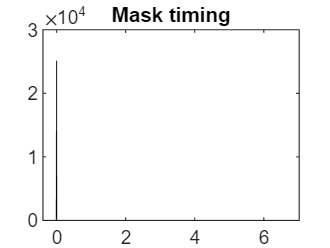

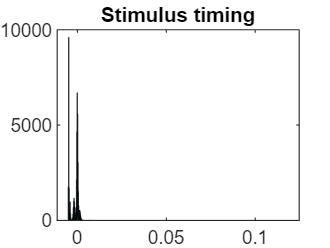

Timin is calculated


% to calculate and plot the timing of stimulus presentation
[timing, d]  = calculate_timing(d, cfg);

### Transfrom data (and trial and subject exclusion)

Exclude subjects with below chance categorization performance.

% make trial exclusion
d = trial_exclusion(d);

0 trials were < 0.1 s
266 trials were > 3 s
6 trials displayed stimulus on wrong frame
11 trials displayed mask on wrong frame
276 trials have been excluded
This equals 0.0055466 % of all trials



% transform data (adds a couple new subtables)
d = transform_data(d, cfg);

Data transformation has been performed




% make subject exclusion -
[d, cfg] = subject_exclusion(d, cfg);

Subject 201 meets all inclusion criteria
Subject 202 meets all inclusion criteria
Subject 203 meets all inclusion criteria
Subject 204 meets all inclusion criteria
Subject 205 meets all inclusion criteria
Subject 206 meets all inclusion criteria
Subject 207 meets all inclusion criteria
Subject 208 meets all inclusion criteria
Subject 209 meets all inclusion criteria
Subject 210 meets all inclusion criteria
Subject 211 meets all inclusion criteria
Subject 212 meets all inclusion criteria
Subject 213 meets all inclusion criteria
Subject 214 meets all inclusion criteria


Subject 216 meets all inclusion criteria
Subject 218 meets all inclusion criteria
Subject 219 meets all inclusion criteria
Subject 220 meets all inclusion criteria
Subject 221 meets all inclusion criteria
Subject 222 meets all inclusion criteria
Subject 224 meets all inclusion criteria
Subject 225 meets all inclusion criteria
Subject 226 meets all inclusion criteria
Subject 227 meets all inclusion criteria
Subject 228 meets all inclusion criteria
Subject 229 meets all inclusion criteria
Subject 230 meets all inclusion criteria
Subject 231 meets all inclusion criteria
Subject 232 meets all inclusion criteria
Subject 233 meets all inclusion criteria
Subject 234 meets all inclusion criteria
Subject 235 meets all inclusion criteria
Subject 236 meets all inclusion criteria
Subject 237 meets all inclusion criteria
Subject 238 meets all inclusion criteria
Subject 240 meets all inclusion criteria
Subject 241 meets all inclusion criteria
Subject 242 meets all inclusion criteria
Subject 243 meet

### Performance

Get categorization task performance

% calculate performance
perf = make_perf(d, cfg);

Performance is calculated
Mean accuracy: 0.71861
Mean RT: 0.82516



### Intersubject correaltions

Build an IS-RDM of how similar people are in the categorization of the stimuli.

Plotting and saving inter-subject RDM for task:mean_neg_RT and bedroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bedroom
Plotting and saving inter-subject RDM for task:IES and bedroom
Plotting and saving inter-subject RDM for task:mean_neg_RT and livingroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and livingroom
Plotting and saving inter-subject RDM for task:IES and livingroom


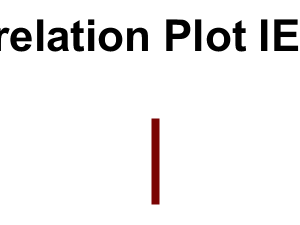

Compare categories


% calculate and plot the correlations of rating between subjects

% get variables of interest
cfg.variables_of_interest = {'mean_neg_RT', 'mean_trial_accuracy', 'IES'};
cfg.colormap = cfg.colormaps.white_zero2;
cfg.plot_rdm = false;
cfg.dissimilarity = true;

[cor_plots, d] = intersub_cor(d, cfg);

### Correlate generated images of typical drawings with DNN layer

Build an IS-RDM on how similar people are in their typical drawings.

% preparation
cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
[cfg.parent_dir, ~, ~] = fileparts(pwd);
images = struct;
cfg.file_format = 'png';
cfg.plot_rdm = 1;
cfg.RDM_of_DNNS = 1;
cfg.analysis_name = 'Own_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'own';
cfg.colormap = cfg.colormaps.typDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 201_bed_gen1.png
Loaded image: 201_bed_gen2.png
Loaded image: 201_bed_gen3.png
Loaded image: 202_bed_gen1.png
Loaded image: 202_bed_gen2.png
Loaded image: 202_bed_gen3.png
Loaded image: 203_bed_gen1.png
Loaded image: 203_bed_gen2.png
Loaded image: 203_bed_gen3.png
Loaded image: 204_bed_gen1.png
Loaded image: 204_bed_gen2.png
Loaded image: 204_bed_gen3.png
Loaded image: 205_bed_gen1.png
Loaded image: 205_bed_gen2.png
Loaded image: 205_bed_gen3.png
Loaded image: 206_bed_gen1.png
Loaded image: 206_bed_gen2.png
Loaded image: 206_bed_gen3.png
Loaded image: 207_bed_gen1.png
Loaded image: 207_bed_gen2.png
Loaded image: 207_bed_gen3.png
Loaded image: 208_bed_gen1.png
Loaded image: 208_bed_gen2.png
Loaded image: 208_bed_gen3.png
Loaded image: 209_bed_gen1.png
Loaded image: 209_bed_gen2.png
Loaded image: 209_bed_gen3.png
Loaded image: 210_bed_gen1.png
Loaded image: 210_bed_gen2.png
Loaded image: 210_bed_gen3.png
Loaded image: 211_bed_gen1.png
Loaded image: 211_bed_gen2.png
Loaded i

analysis Own_drawing_DNN_RDM - layer #1 - category: bedroom
Length of labels do not match matrix dimensions


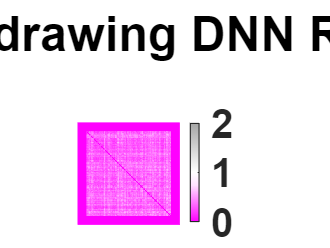

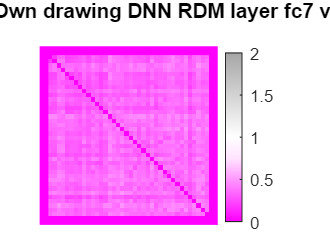

analysis Own_drawing_DNN_RDM - layer #1 - category: livingroom
Length of labels do not match matrix dimensions


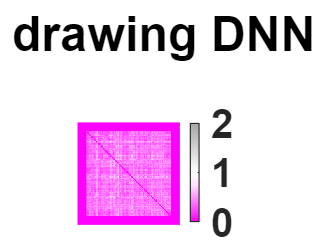

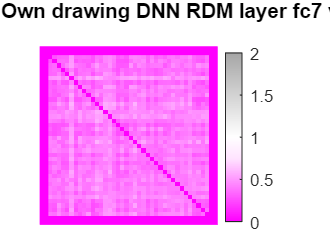


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

Calculated correaltion of DNN layer representation of Own_drawing_DNN_RDM with task RDMs for bedroom
Calculated correaltion of DNN layer representation of Own_drawing_DNN_RDM with task RDMs for livingroom


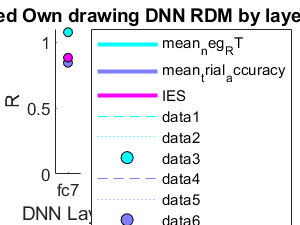


% correlate similarities between subs with intersubject RDMs for each task
cfg.plot_rdm = 0;
plot_dnn_cor_by_layer(d, cfg);

### Correlate generated images of control drawings with DNN layer

Build an IS-RDM on how similar people are in their control drawings.

% preparation
cfg.analysis_name = 'Control_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
cfg.plot_rdm = 1;
drw_group = 'control';
cfg.colormap = cfg.colormaps.ctrDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp2', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 201_bed_copy_gen1.png
Loaded image: 201_bed_copy_gen2.png
Loaded image: 201_bed_copy_gen3.png
Loaded image: 202_bed_copy_gen1.png
Loaded image: 202_bed_copy_gen2.png
Loaded image: 202_bed_copy_gen3.png
Loaded image: 203_bed_copy_gen1.png
Loaded image: 203_bed_copy_gen2.png
Loaded image: 203_bed_copy_gen3.png
Loaded image: 204_bed_copy_gen1.png
Loaded image: 204_bed_copy_gen2.png
Loaded image: 204_bed_copy_gen3.png
Loaded image: 205_bed_copy_gen1.png
Loaded image: 205_bed_copy_gen2.png
Loaded image: 205_bed_copy_gen3.png
Loaded image: 206_bed_copy_gen1.png
Loaded image: 206_bed_copy_gen2.png
Loaded image: 206_bed_copy_gen3.png
Loaded image: 207_bed_copy_gen1.png
Loaded image: 207_bed_copy_gen2.png
Loaded image: 207_bed_copy_gen3.png
Loaded image: 208_bed_copy_gen1.png
Loaded image: 208_bed_copy_gen2.png
Loaded image: 208_bed_copy_gen3.png
Loaded image: 209_bed_copy_gen1.png
Loaded image: 209_bed_copy_gen2.png
Loaded image: 209_bed_copy_gen3.png
Loaded image: 210_bed_copy_g

analysis Control_drawing_DNN_RDM - layer #1 - category: bedroom
Length of labels do not match matrix dimensions


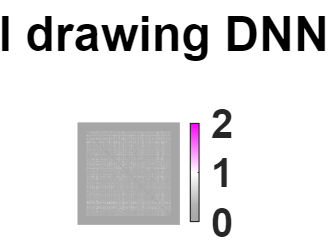

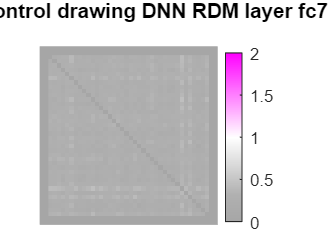

analysis Control_drawing_DNN_RDM - layer #1 - category: livingroom
Length of labels do not match matrix dimensions


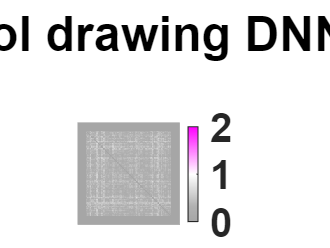

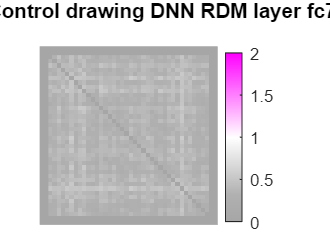


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

Calculated correaltion of DNN layer representation of Control_drawing_DNN_RDM with task RDMs for bedroom
Calculated correaltion of DNN layer representation of Control_drawing_DNN_RDM with task RDMs for livingroom


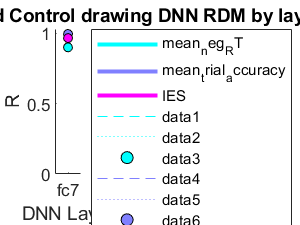


% correlate similarities between subs with intersubject RDMs for each task
cfg.plot_rdm = 0;
plot_dnn_cor_by_layer(d, cfg);

### Correlate generated images of control images with DNN layer

Main analysis step. IS-RDMs of drawings and task performance are compared here. Expected output is Figure 2C and corresponding statistical results.

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 10000 permutations...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bedroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 10000 permutations...
Compare inter-subject RDM of IES with correaltion of predictor RDMs - livingroom
*partial* Typical Images vgg16_imagenet Late
FDR corrected p value for IES: 0.0385 *
R value for IES: 0.14285


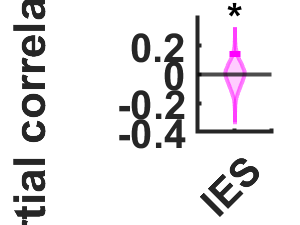

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = true;
cfg.plotting = true;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'generated_images_own_dnn_layer_late', 'generated_images_ctr_dnn_layer_late'};
cfg.tasks_of_interest = {'IES'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.add_legend = false;
cfg.ylim = [-0.4, 0.4];
cfg.plotting_predictors = 1;
cfg.plott_gap = 0;
cfg.partial_correlation_type = 'Pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 10000 permutations...
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bedroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 10000 permutations...
Compare inter-subject RDM of IES with correaltion of predictor RDMs - livingroom
*partial* Control Images vgg16_imagenet Late
FDR corrected p value for IES: 0.3383  
R value for IES: 0.029137


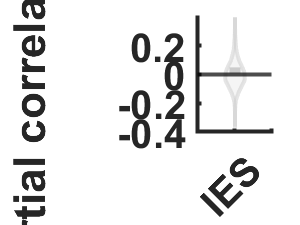


cfg.plotting_predictors = 2;
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);